## Lecture 3: Lattice Structures

A lattice filter is an example of an all-pass filter typically used the analysis and synthesis of speech signals.

### All-zero lattice structure  

An ***all-zero*** lattice models an FIR system.

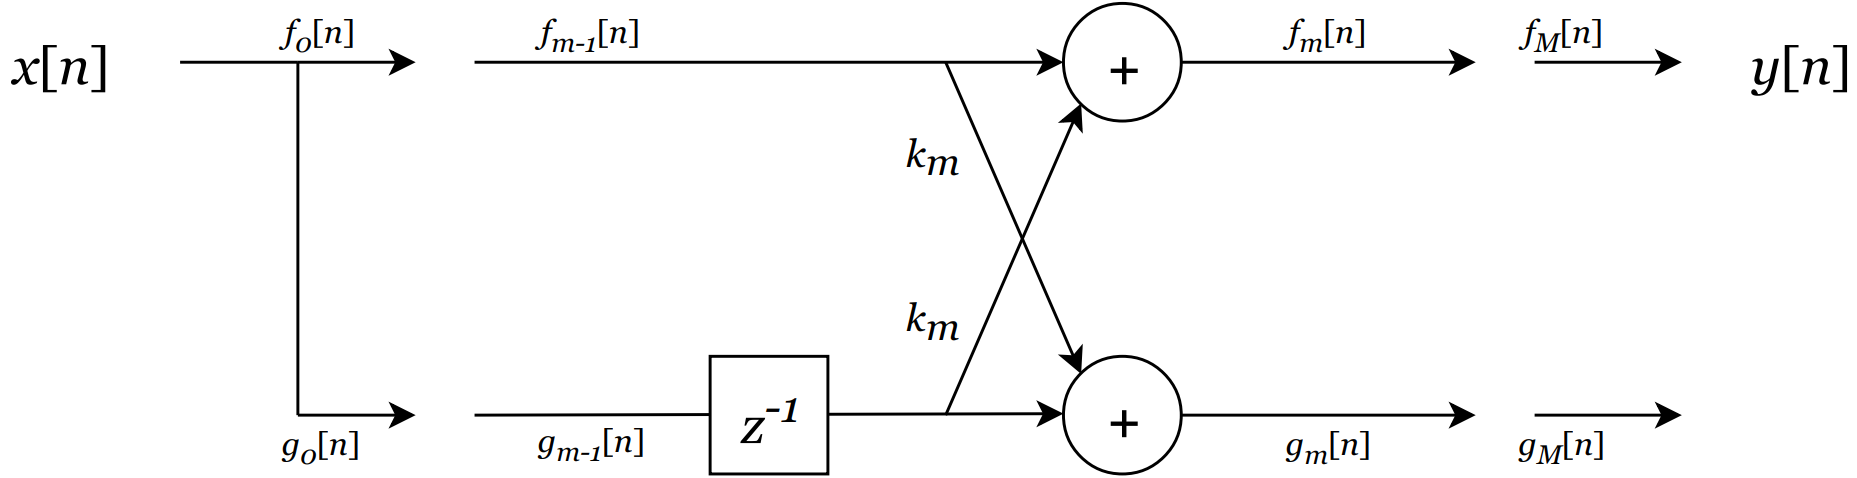

Each section has two inputs ($f_{m-1} \left\lbrack n\right\rbrack$ and $g_{m-1} \left\lbrack n-1\right\rbrack$) and two outputs $\left(f_m \left\lbrack n\right\rbrack ,g_m \left\lbrack n\right\rbrack \right)$. 

The $m$'th section/stage can be computed as follows:

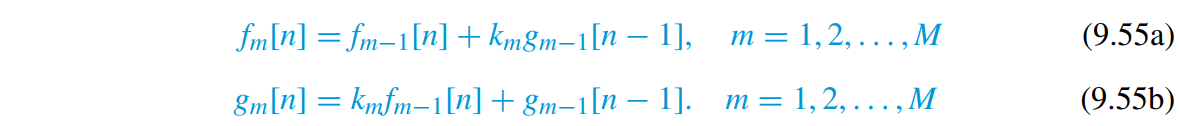

The overall system input and output are given by:

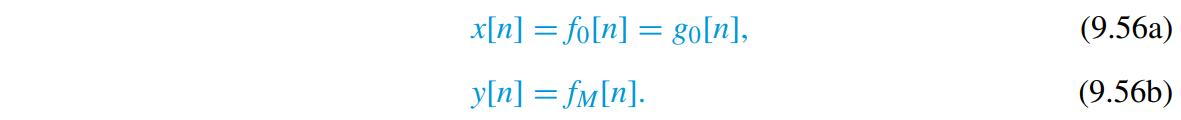

In general, the outputs of the *m*th section correspond to two FIR filters with the same coefficients but in reverse order:

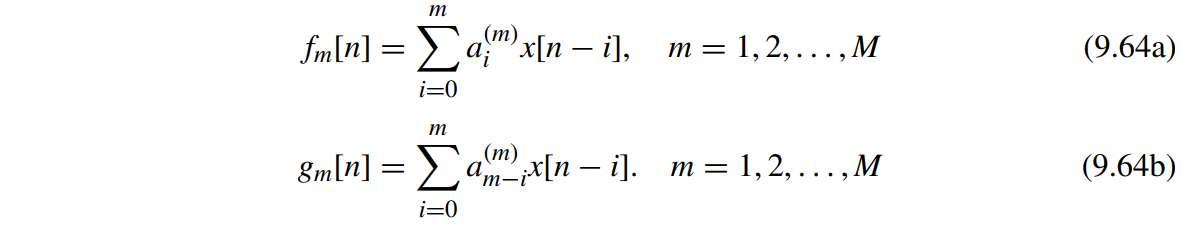

The system functions of these all-zero FIR filters are given by:

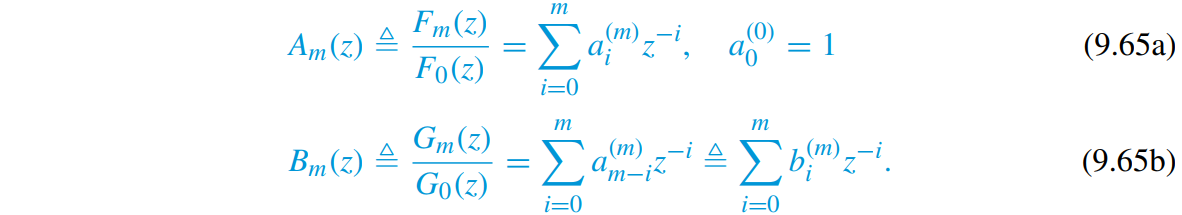

Suppose we have a FIR system of the form:


$$H\left(z\right)=\sum_{k=0}^M h\left\lbrack k\right\rbrack z^{-1}$$


We can start taking the z-transforms.

Since $z\left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack$, taking the z-transform is straightforward:


$$X\left(z\right)=F_0 \left(z\right)=G_0 \left(z\right)$$


The difference equations of the $m$th section is:


$$\begin{array}{l}
f_m \left\lbrack n\right\rbrack =f_{m-1} \left\lbrack n\right\rbrack +k_m g_{m-1} \left\lbrack n-1\right\rbrack \\
g_m \left\lbrack n\right\rbrack =k_m \;f_{m-1} \left\lbrack n\right\rbrack +g_{m-1} \left\lbrack n-1\right\rbrack 
\end{array}$$


Taking the z-transform of the $m$th section gives us:


$$\begin{array}{l}
F_m \left(z\right)=F_{m-1} \left(z\right)+k_m G_{m-1} \left(z\right)z^{-1} \\
G_m \left(z\right)=k_m F_{m-1} \left(z\right)+G_{m-1} \left(z\right)z^{-1} 
\end{array}$$


We can normalise these two z-transforms as follows:


$$A_m \left(z\right)=\frac{F_m \left(z\right)}{F_0 \left(z\right)}=A_{m-1} \left(z\right)+k_m B_{m-1} \left(z\right)z^{-1}$$



$$B_m \left(z\right)=\frac{G_m \left(z\right)}{G_0 \left(z\right)}=k_m A_{m-1} \left(z\right)+B_{m-1} \left(z\right)z^{-1}$$


By the way we normalise, we notice that $A_0 \left(z\right)=B_0 \left(z\right)=1$ because

$A_0 =\frac{F_0 \left(z\right)}{F_0 \left(z\right)}=1$ and $B_0 =\frac{G_0 \left(z\right)}{G_0 \left(z\right)}=1$

Because of the normalisation, we can write:


$$H\left(z\right)=h\left\lbrack 0\right\rbrack A_M \left(z\right)$$


#### Single-stage filter

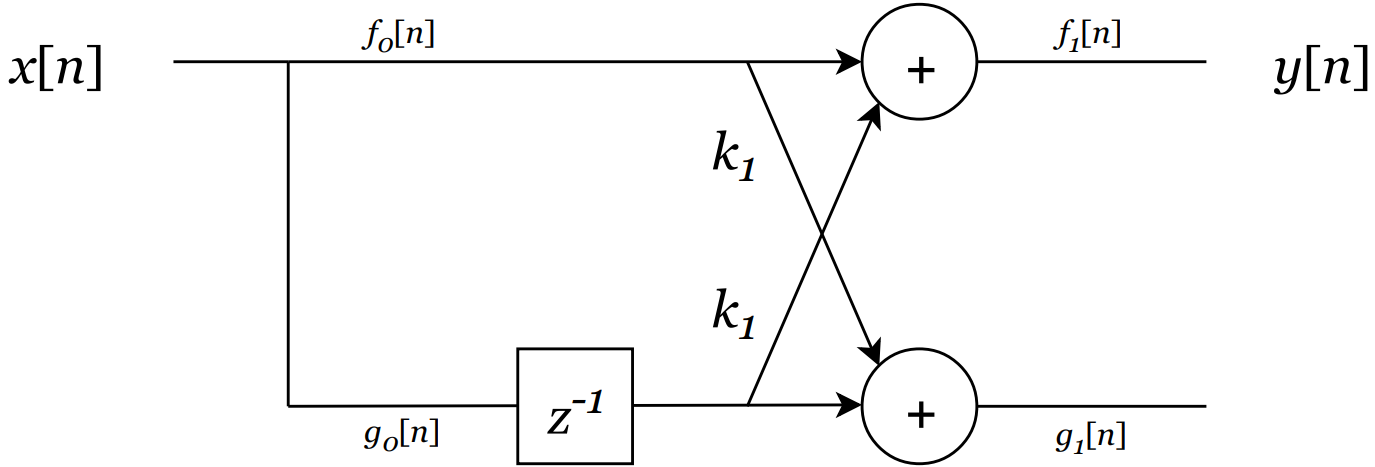

#### Two stage filter

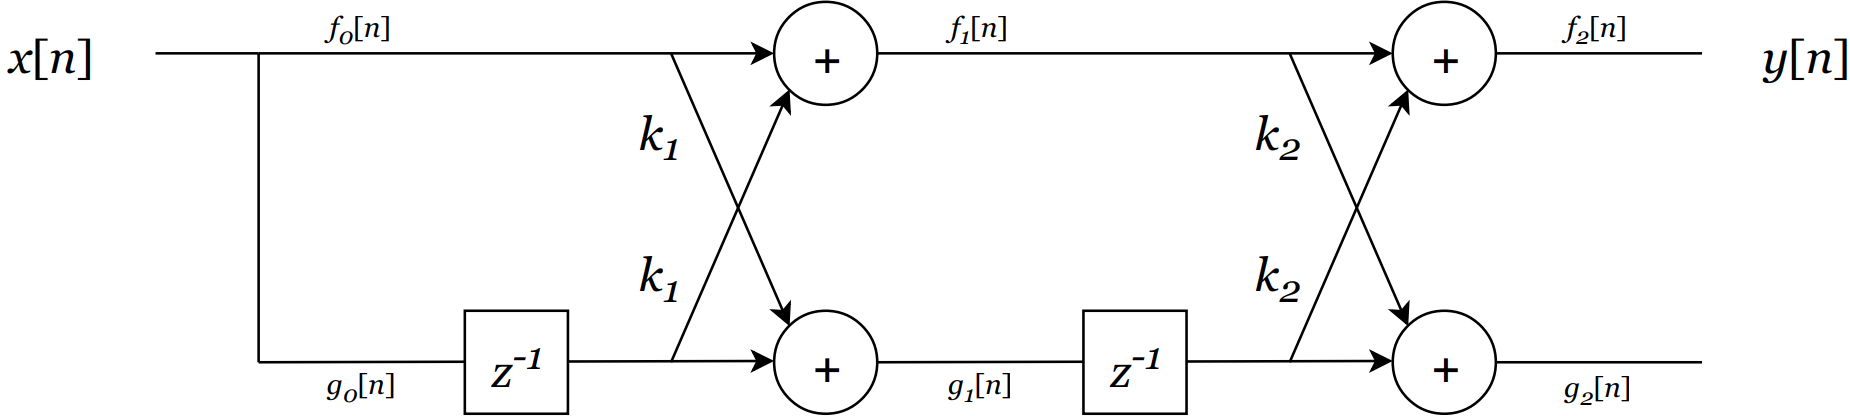

Compute the difference equations for the two FIR systems:


$$\begin{array}{l}
f_2 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack +k_2 g_1 \left\lbrack n-1\right\rbrack \\
g_2 \left\lbrack n\right\rbrack =k_2 \;f_1 \left\lbrack n\right\rbrack +g_1 \left\lbrack n-1\right\rbrack 
\end{array}$$



$$\begin{array}{l}
f_1 \left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack +k_1 g_0 \left\lbrack n-1\right\rbrack \\
g_1 \left\lbrack n\right\rbrack =k_1 \;f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack 
\end{array}$$


If we substitute we get:


$$\begin{array}{l}
f_2 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack +k_2 g_1 \left\lbrack n-1\right\rbrack \\
f_2 \left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack +k_1 g_0 \left\lbrack n-1\right\rbrack +k_2 \left(k_1 \;f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack \right)
\end{array}$$


Since $x\left\lbrack n\right\rbrack =f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack$ and $y\left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack$ then we can rewrite the difference equation for two stage all-zero lattice filter as:


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack +k_1 \left(1+k_2 \right)x\left\lbrack n-1\right\rbrack +k_2 x\left\lbrack n-2\right\rbrack$$


Taking the z-transform, we have:


$$Y\left(z\right)=X\left(z\right)+k_1 \left(1+k_2 \right)z^{-1} X\left(z\right)+k_2 z^{-2} X\left(z\right)$$


We can compute the transfer function:


$$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=1+k_1 \left(1+k_2 \right)z^{-1} +k_2 z^{-2}$$


#### Three stage filter

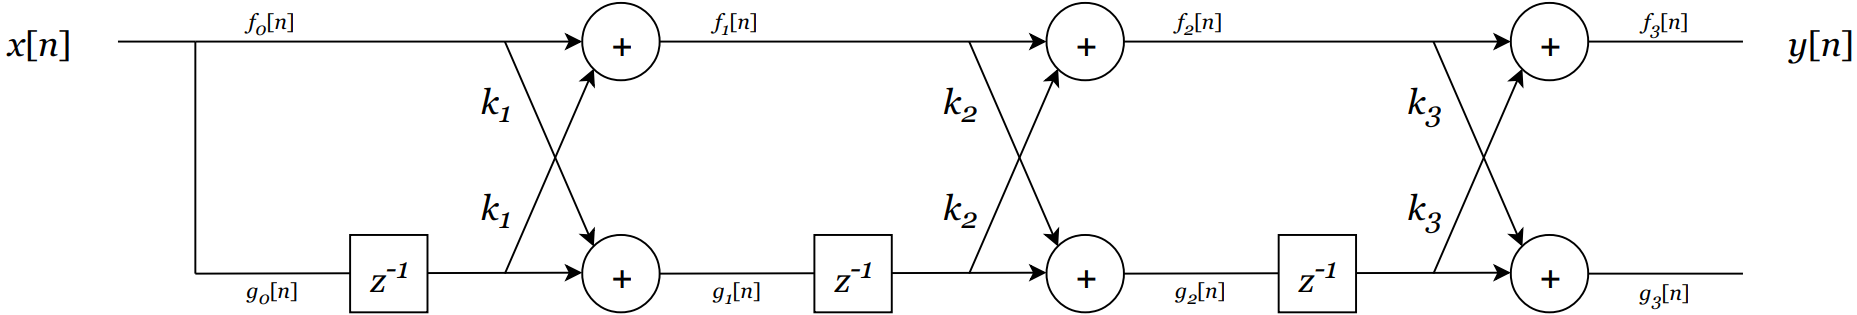

#### How to find reflection coefficients from the impulse response?

Suppose we want to determine the reflection coefficients $k_m ,m=1,2,\cdots ,M$ from the following an $M$th-order normalised FIR filter:


$$H\left(z\right)=\sum_{k=0}^M h\left\lbrack k\right\rbrack z^{-1}$$


First, we can define the filter coefficients as follows:

$a_k =\frac{h\left\lbrack k\right\rbrack }{h\left\lbrack 0\right\rbrack }$ where $k=0,1,\cdots ,M$

The recursive algorithm works as follows:

- Compute $A_M \left(z\right)=\frac{H\left(z\right)}{h\left\lbrack 0\right\rbrack }$

- Compute $k_M =a_M$ where $a_M$ is the last coefficients of $A_M \left(z\right)$. For example, if $A_M \left(z\right)=1+0\ldotp 06z^{-1} -0\ldotp 42z^{-2} +0\ldotp 5z^{-3}$ then $k_M =0\ldotp 5$

- Compute $B_M \left(z\right)$ by flipping the coefficients of $A_M \left(z\right)$

- Set $m=M$

- Compute $A_{m-1} \left(z\right)=\frac{1}{1-k_m^2 }\left\lbrack A_m \left(z\right)-k_m B_m \left(z\right)\right\rbrack$. Notice that this is where the algorithm fails because if $k_m =1\to k_m^2 =1$ then we will have division by zero.

- Compute $k_{m-1} =a_{m-1}$ where $a_{m-1}$ is the last coefficients of $A_{m-1} \left(z\right)$

- Compute $B_{m-1} \left(z\right)$ by flipping the coefficients of $A_{m-1} \left(z\right)$. Alternatively, compute $B_{m-1} \left(z\right)=z^{-m-1} A_{m-1} \left(\frac{1}{z}\right)$

- Set $m=m-1$

- Go to step 5 if $m\not= 0$

- We know that $A_0 \left(z\right)=B_0 \left(z\right)=1$

See page 513

### All-pole lattice structure

An ***all-pole*** lattice models an IIR system.

The figure below shows how an all-pole lattice structure looks like

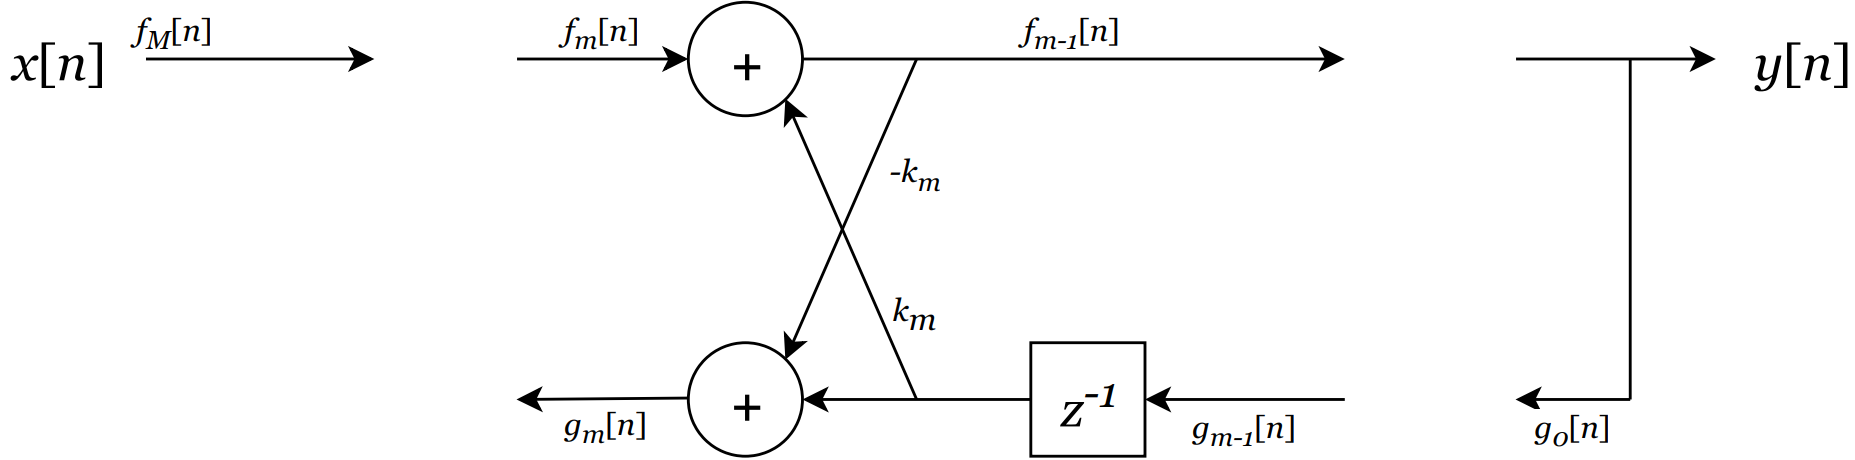


$$f_{m-1} \left\lbrack n\right\rbrack =f_m \left\lbrack n\right\rbrack -k_m g_{m-1} \left\lbrack n-1\right\rbrack$$



$$g_m \left\lbrack n\right\rbrack =k_m f_{m-1} \left\lbrack n\right\rbrack +g_{m-1} \left\lbrack n-1\right\rbrack$$


When $M=1$

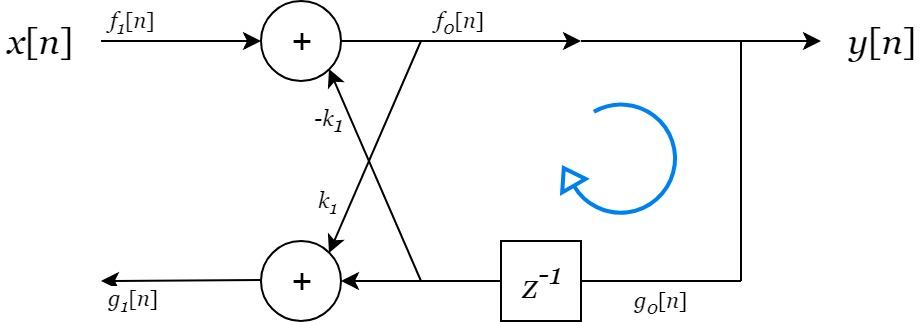

The difference equation for when $M=1$ is given as:


$$f_0 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack$$


Since $f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack$ and $f_1 \left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack$ then we have the following difference equation


$$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -k_1 y\left\lbrack n-1\right\rbrack$$


This is the difference equation for a IIR filter!

If we take the z-transform, we get:


$$Y\left(z\right)=X\left(z\right)-k_1 Y\left(z\right)z^{-1}$$


We can compute the transfer function:


$$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{1}{1+k_1 z^{-1} }=\frac{1}{A\left(z\right)}$$


Let us look at the other system $g_1 \left\lbrack n\right\rbrack$:


$$\begin{array}{l}
g_1 \left\lbrack n\right\rbrack =k_1 f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack \\
g_1 \left\lbrack n\right\rbrack =k_1 y\left\lbrack n\right\rbrack +y\left\lbrack n-1\right\rbrack 
\end{array}$$


It is clear that $g_1 \left\lbrack n\right\rbrack$ is a FIR filter of the output.

When $M=2$

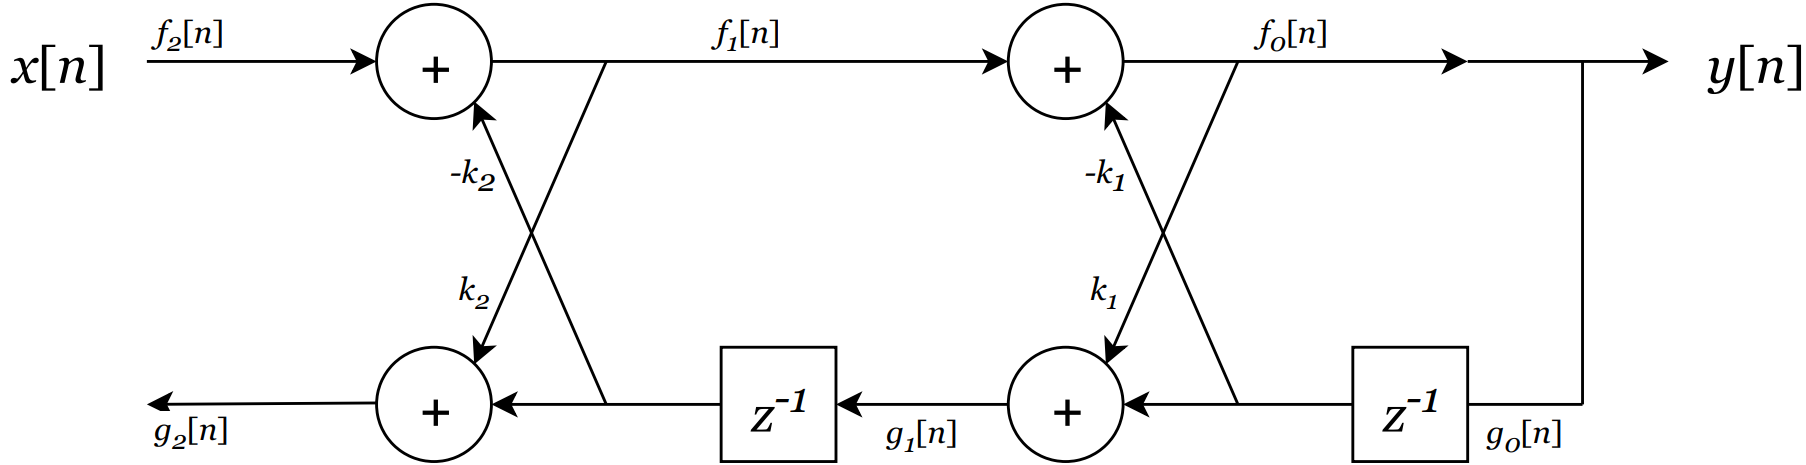

We compute the difference equations from the output:


$$f_0 \left\lbrack n\right\rbrack =f_1 \left\lbrack n\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack$$



$$g_1 \left\lbrack n\right\rbrack =k_1 f_0 \left\lbrack n\right\rbrack +g_0 \left\lbrack n-1\right\rbrack$$


The next stage:


$$f_1 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack$$



$$g_2 \left\lbrack n\right\rbrack =k_2 f_1 \left\lbrack n\right\rbrack +g_1 \left\lbrack n-1\right\rbrack$$


We can substitute:


$$\begin{array}{l}
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 g_1 \left\lbrack n-1\right\rbrack -k_1 g_0 \left\lbrack n-1\right\rbrack \\
f_0 \left\lbrack n\right\rbrack =f_2 \left\lbrack n\right\rbrack -k_2 \left(k_1 f_0 \left\lbrack n-1\right\rbrack +g_0 \left\lbrack n-2\right\rbrack \right)-k_1 g_0 \left\lbrack n-1\right\rbrack 
\end{array}$$


Since $f_0 \left\lbrack n\right\rbrack =g_0 \left\lbrack n\right\rbrack =y\left\lbrack n\right\rbrack$ and $f_2 \left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack$ then we have:


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -k_2 \left(k_1 y\left\lbrack n-1\right\rbrack +y\left\lbrack n-2\right\rbrack \right)-k_1 y\left\lbrack n-1\right\rbrack \\
y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -k_1 \left(1+k_2 \right)y\left\lbrack n-1\right\rbrack -k_2 y\left\lbrack n-2\right\rbrack 
\end{array}$$


If we take the z-transform, we get:


$$Y\left(z\right)=X\left(z\right)-k_1 \left(1+k_2 \right)Y\left(z\right)z^{-1} -k_2 Y\left(z\right)z^{-2}$$


The transfer function becomes:


$$\frac{Y\left(z\right)}{X\left(z\right)}=\frac{1}{1+k_1 \left(1+k_2 \right)z^{-1} +k_2 z^{-2} }$$


#### Stability of all-pole filters

When is an all-pole filter stable?

The all-zero and all-pole lattice structures require twice the number of multiplications per output sample as the direct forms. However, they have two unique advantages compared to direct form structures. 

The first advantage follows from the following theorem:  

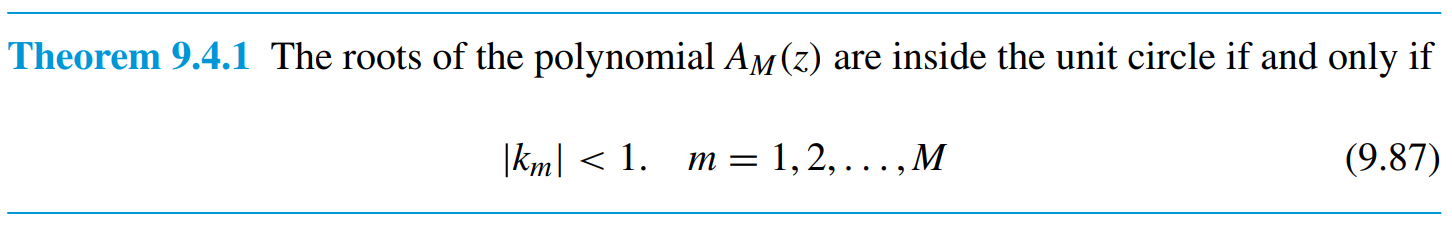

If the lattice parameters satisfy (9.87) then the all-zero lattice filter is minimum-phase and the all-pole filter is stable.

The second advantage is that lattice structures are insensitive to quantization of the *k*-parameters.  